# Transfer Learning with MATLAB

In this exercise, you will use transfer learning to classify images into 1 of 5 different aircraft categories.

- 737-800

- 747-200

- A320

- A380

- Gulfstream V

## Create a Datastore

We used a datastore previously to read images in a loop. With ImageDatastore you can also label images, set a custom read function and split images into different sets. 

Create a datastore, including subdirectories and add labels based on the filenames.

filePath = "Images";

imds = imageDatastore(filePath,...  
    'IncludeSubfolders',true,...
    'LabelSource','foldernames'); 

disp("Datastore loaded.")

## Look at Images from Dataset

Let's get a feel for the dataset. Write some code that will let you inspect some of the images. You can get the label from the list of labels or from the second output of the datastore read functions.

numToDisplay = 5;

displayImages(imds, numToDisplay);

## Splitting Image datastore into 3 sets:  | Train | Validate | Test |

It is a best practice to split our data into a training, validation and test set.

- Training - used to train our network by establishing proper weights that allow for accurate classification

- Validation - a dataset that you test the network on during or after training. If the results are poor, retrain the network with different hyperparameters and/or network architecture

- Test - an unseen dataset that is used as an unbiased measurement of network accuracy. Use this after you are happy with your validation performance.

There is not a perfect way to split your data, but people often do a 70/15/15 split. Use the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/datastore.spliteachlabel.html) function to split your datastore into the three desired sets.

[trainDS, valDS, testDS] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

## Deep Network Designer

We will perform the entire transfer learning workflow in the Deep Network Designer app.

To open the Deep Network Designer app, click on the "Apps" tab, then "Deep Network Designer".

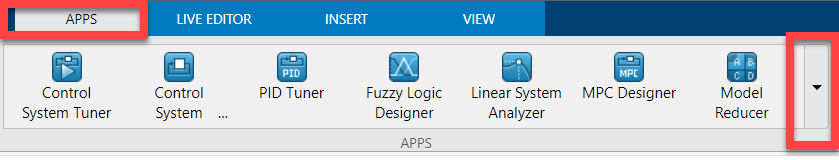

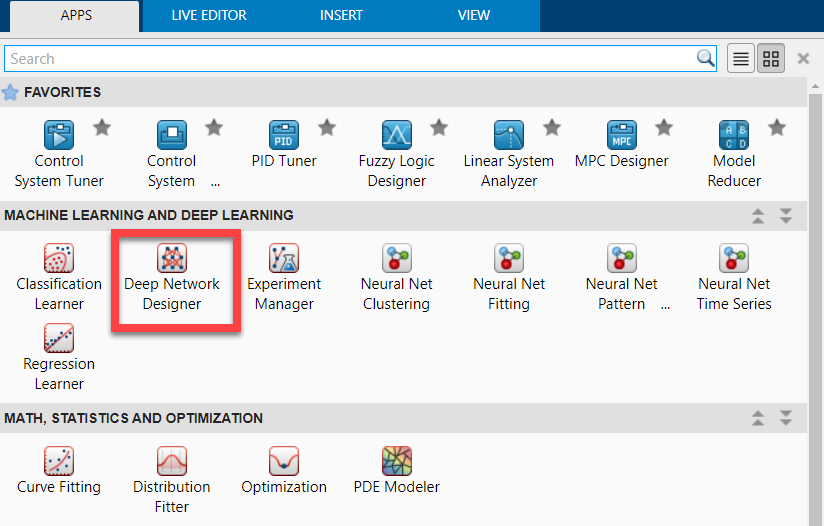

If you** cannot open the Deep Network Designer app**, open the script below

% edit TransferLearningWithoutDND.mlx

#### Step 1: Import AlexNet

In transfer learning the majority of the layers stay the same. We need to modify the last few layers to fit our specific dataset. 

First, import AlexNet from the Deep Network Designer app. 

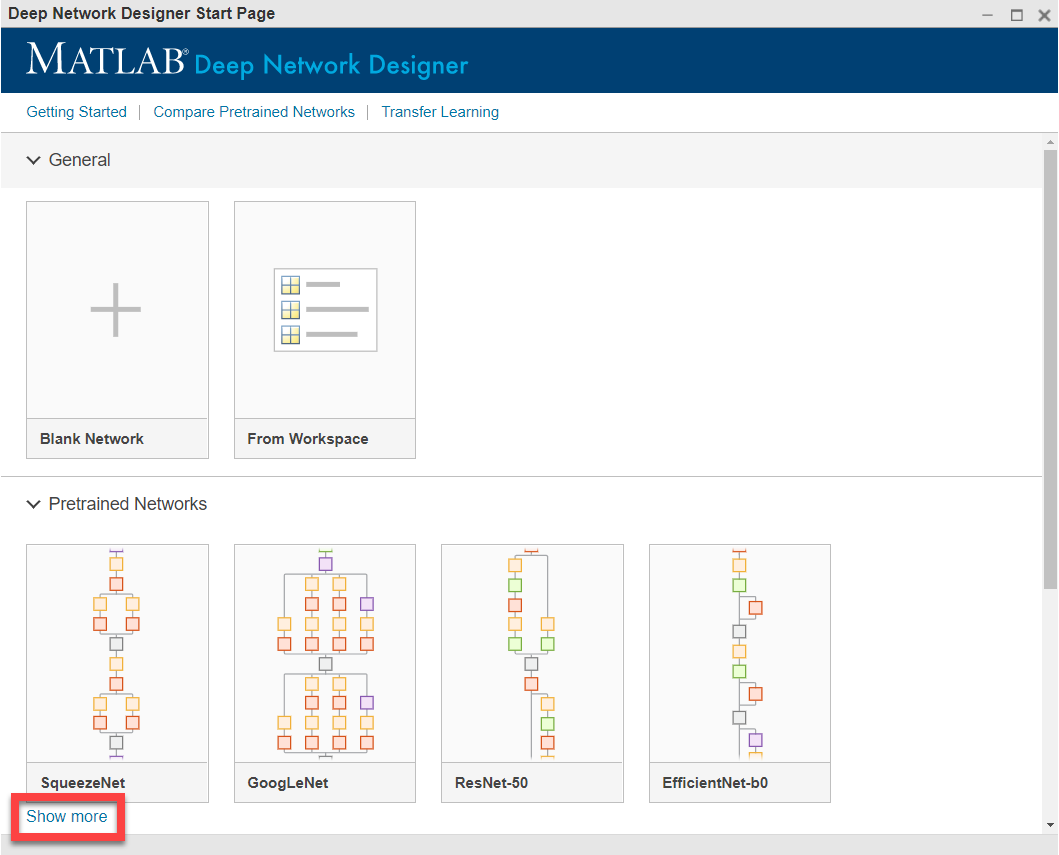

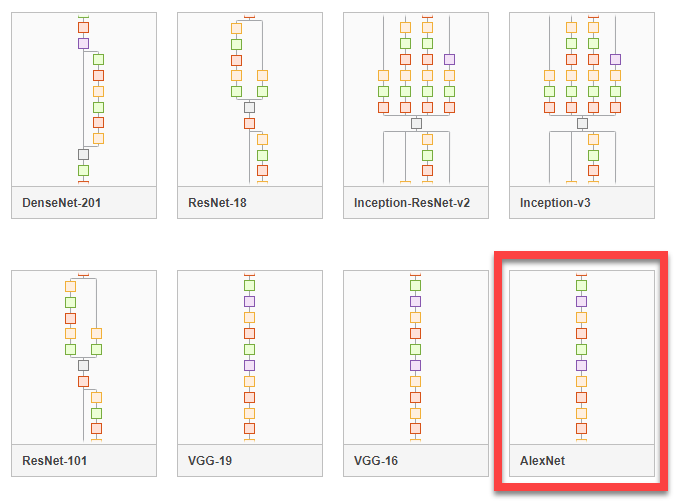

#### Step 2: Modify Alexnet

Instructions:

- Remove the last three layers in the network

- Add in a new Fully Connected Layer, Softmax Layer, and Classification Layer

- In the **fullyConnectedLayer**, change **OutputSize = 5**

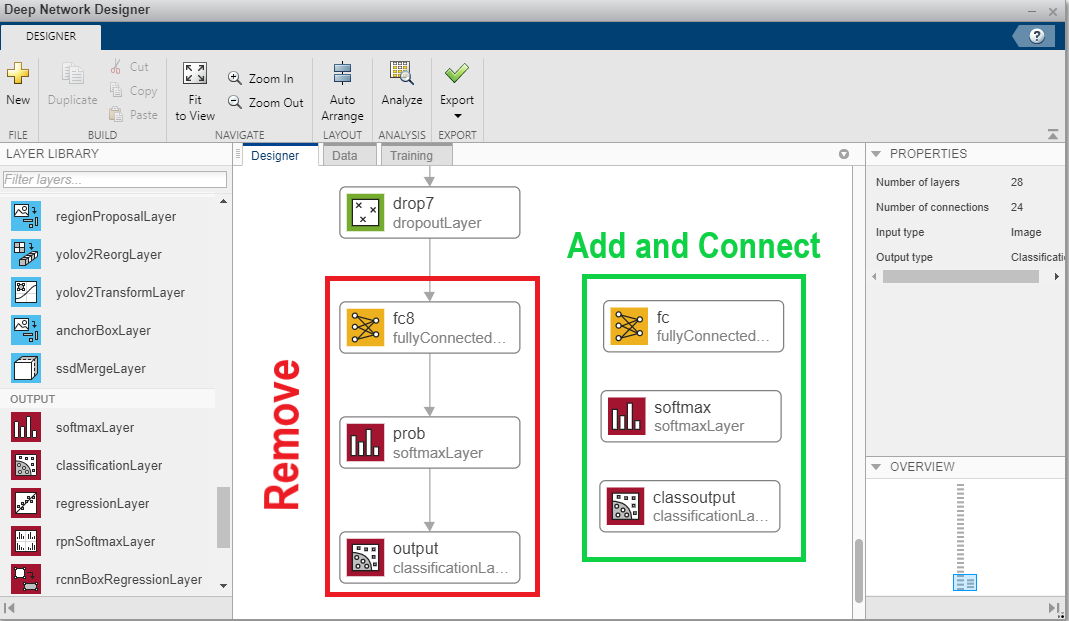

#### Step 3: Specify Data for Training and Validation

Go to the "Data" tab of the Deep Network Designer app. 

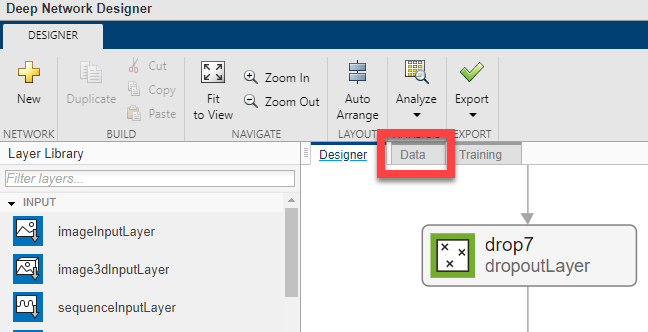

Select "Import Image Data", then specify the training and validation datastores. Then, click "Import". 

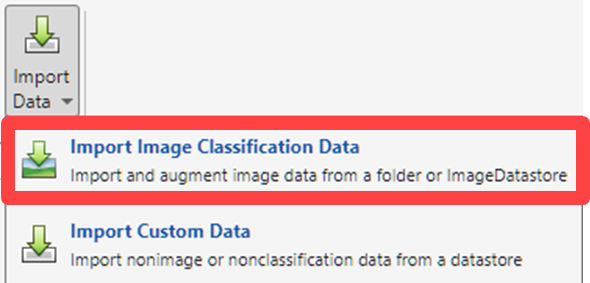

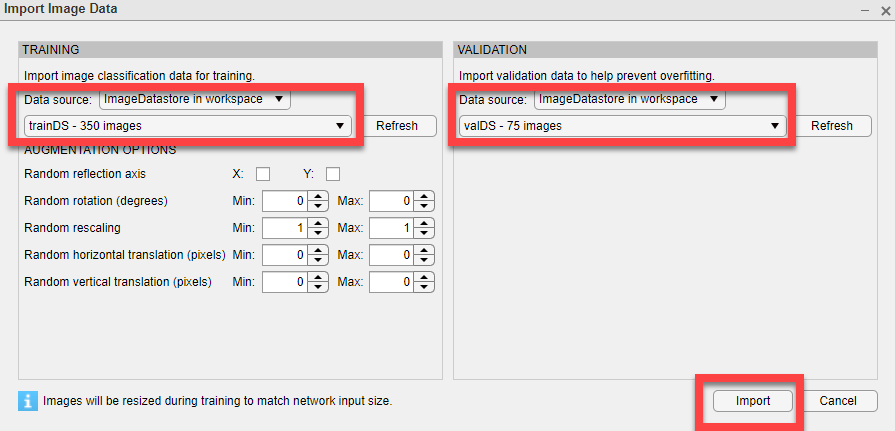

#### Step 4: Adjust Training Options

Go to the "Training" tab of the Deep Network Designer app.

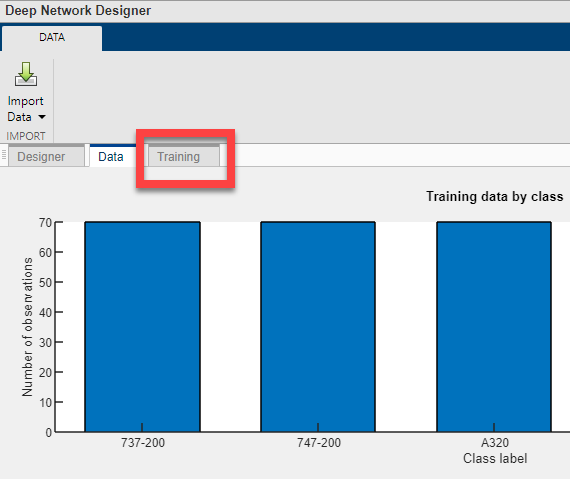

Edit the training options.

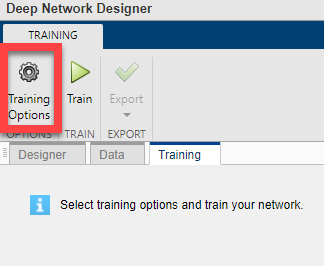

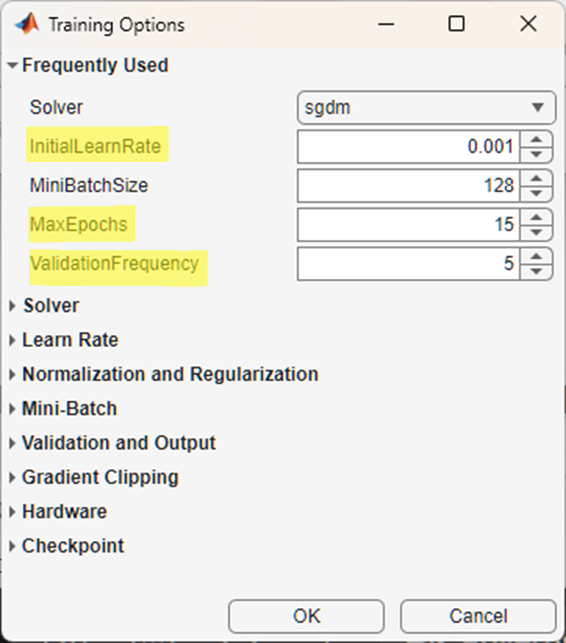

#### Step 5: Train the Network and Export the Results

Train the network.

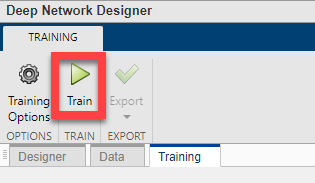

Export the results.

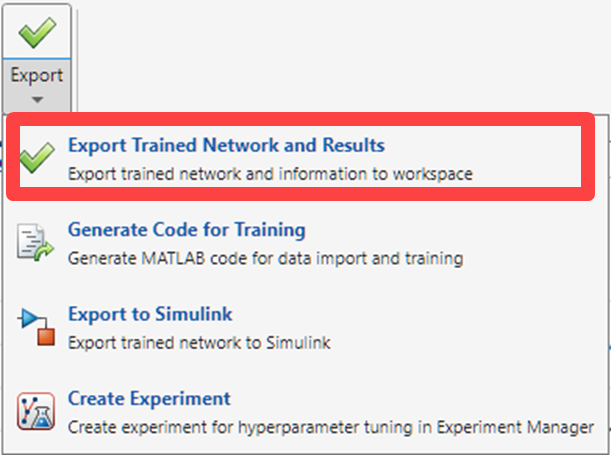

Note the variable name of the exported network. You will be using this network in the rest of this exercise.

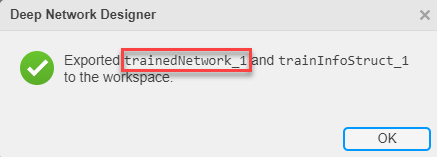

## Load Trained Network

load("Data/trainedNetwork_1.mat");
disp("Saved network loaded.")

## Test the Network

Once happy with validation results, test the network on the test dataset uisng the arguments below:

- your_network = Trained Network

- your_datastore = Resized Test Datastore

inputSize = [227 227];
resizedTestDS = augmentedImageDatastore(inputSize, testDS);

% Classify images in the entire datastore 
% HINT - Use the following syntax: [labels, scores] = classify(your_network, your_datastore)

% WRITE CODE BELOW


disp("Scores calculated.")

## Calculate Accuracy

Try to answer the following questions:

- Are there trends in misclassification?

- Where might these trends come from?

accuracy = sum(labels == testDS.Labels)/numel(labels)
figure
% Confusion Matrix - visual inspection of accuracy and error
cm = confusionchart(labels, testDS.Labels);
cm.RowSummary = 'row-normalized';
cm.Title = 'Aircraft Classification Confusion Matrix';

## View Some of the Results

Write a script that will let you view some of the images in the test dataset

numImages = 5;
for ii=1:numImages
    figure
    [img, info] = read(testDS);
    imshow(img)

    % Add code here to RESIZE and CLASSIFY the image 
    % hint: use the variable "inputSize" and the function "imresize"
    % hint: use the "classify" function and set its output to a variable named "pred"

    % WRITE CODE BELOW



    % DO NOT MODIFY THE FOLLOWING
    title("Predicted: " + string(pred) + ", Actual: " + string(info.Label))
    axis image
end

## Visualization

There are different methods for obtaining insight on what parts of the image the network "looks" at when making its prediction. For more information on this, please refer to [this documentation page](https://www.mathworks.com/help/deeplearning/deep-learning-visualization.html).

visualizationType = "Grad-CAM";
net = trainedNetwork_1;

showVisualization(testDS, net, visualizationType);

## Helper Functions

function displayImages(imds, numToDisplay)

tiledlayout('flow', 'TileSpacing', 'Compact');

for ii=1:numToDisplay
    nexttile
    
    % Generate random number < # of total images
    randNum = randi(length(imds.Files));
    
    % Read random image from the datastore and visualize
    [imTemp,info] = readimage(imds,randNum);
    imshow(imTemp)
    title(char(info.Label),'Interpreter','none')
end

end

function showVisualization(testDS, net, visualizationType)
reset(testDS)
numImages = 5;

for ii = 1:numImages
    figure
    inputSize = net.Layers(1).InputSize(1:2);
    [origImg, info] = read(testDS);
    origSize = size(origImg);
    img = imresize(origImg,inputSize);
    [label,score] = classify(net,img);
    score = max(score);
    
    switch visualizationType
        
        case "occlusion sensitivity"
            
            map = occlusionSensitivity(net,img,label);
            map = imresize(map, origSize(1:2));
            imshow(origImg)
            hold on
            imagesc(map,'AlphaData',0.5);
            hold off
            colormap jet
            title(["Method: Occlusion Sensitivity",...
                "Predicted: " + string(label) + " (" + score + "), Actual: " + string(info.Label)]);
            
        case "Grad-CAM"
            
            map = gradCAM(net,img,label);
            map = imresize(map, origSize(1:2));
            imshow(origImg);
            hold on;
            imagesc(map,'AlphaData',0.5);
            colormap jet
            hold off;
            title(["Method: Grad-CAM",...
                "Predicted: " + string(label) + " (" + score + "), Actual: " + string(info.Label)]);
            
    end
end
end

## References

Data source: [http://www.robots.ox.ac.uk/~vgg/data/fgvc-aircraft/](http://www.robots.ox.ac.uk/~vgg/data/fgvc-aircraft/)

Fine-Grained Visual Classification of Aircraft, S. Maji, J. Kannala, E. Rahtu, M. Blaschko, A. Vedaldi, arXiv.org, 2013

*Copyright 2024 The MathWorks, Inc.*